# Sp2n型量子群の表現を構築するための代数構造の多項式表示

## 動機

C_n型量子群のmodule algebraは非可換変数としては既に得られている。これを可換変数で表示したい。

そのために可換変数で積構造の微分演算子による表示を解析する。

C_2型は既に達成されているので、一般化を試みる。

quantum symplectic spaceの定義をする。

## Uq(sp_2n)-modalgの定義

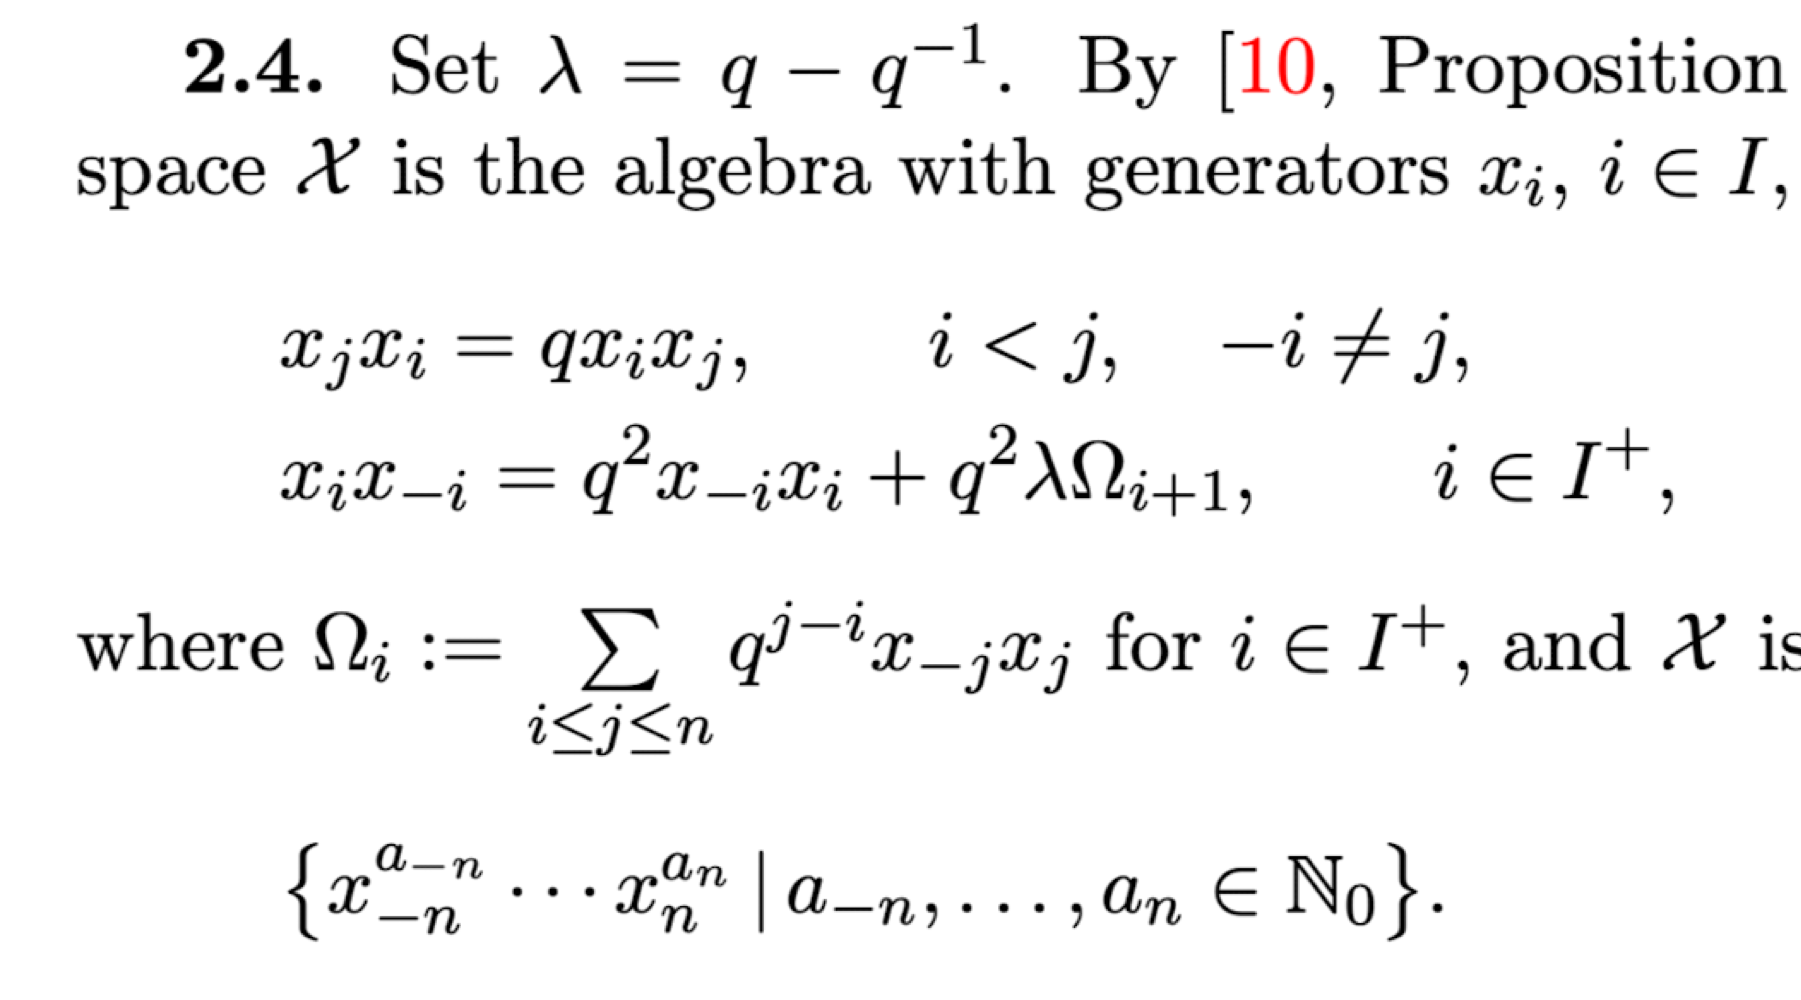

syms q
set(CR.H,di=1)
s=@simplify;

## Uqsp4modalgクラスによる規則性の発見

### strAlgによる計算

ll=2;
% [O,Xm2,Xm1,X1,X2]=strCnmodalg.getGenerator(ll,"all");
[O,X]=StrCnmodalg.getGenerator(ll,"dict");

計算の確認

Xm1*X2*Xm1*X1

関数または変数 'Xm1' が認識されません。

X1^2*Xm1^2
X1^2*Xm1^5

a=2;
am1=1;
A1=X(1)^a*X(-1)^am1*q^{-2*a*am1}

A1 =         coeff            base    
    _____________    ____________
    (q^4 - 1)/q      x_m3 x_1 x_3
    (q^4 - 1)/q^2    x_m2 x_1 x_2
    1                x_m1 x_1 x_1

A1.cf=s(A1.cf./cellfun(@(pw)gtN(pw,am1,a),A1.pw))

A1 =             coeff                base    
    _____________________    ____________
    (q^4 + q^2)/(q^2 - 1)    x_m3 x_1 x_3
    (q^3 + q)/(q^2 - 1)      x_m2 x_1 x_2
    q^3/(q^2 - 1)^2          x_m1 x_1 x_1

function ret=gtN(pw,am1,a1)
    qN=qNumS;
    syms q
    tau=qN.tau(q);
    l=length(pw)/2;
    N=a1-sum(pw==l+1);
    ret=tau^(N)*q^(-N*(N-1)/2)*qN.fac(q,a1)*qN.fac(q,am1)/qN.fac(q,a1-N)/qN.fac(q,am1-N)/qN.fac(q,N);
end

A1=X(1)^2*X(-1)^2

A1 =               coeff                    base       
    _________________________    _________________
    q^6*(q^2 - 1)^2*(q^2 + 1)    x_m3 x_m3 x_3 x_3
    q^5*(q^4 - 1)^2              x_m3 x_m2 x_2 x_3
    q^6*(q^2 - 1)*(q^2 + 1)^2    x_m3 x_m1 x_1 x_3
    q^4*(q^2 - 1)^2*(q^2 + 1)    x_m2 x_m2 x_2 x_2
    q^5*(q^2 - 1)*(q^2 + 1)^2    x_m2 x_m1 x_1 x_2
    q^8                          x_m1 x_m1 x_1 x_1

for ii=2:4
    B1=X(1)^2*X(-1)^ii;
    disp(s(B1.cf./A1.cf).')
end

$$\left(\begin{array}{cccccc} 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccccc} q^{6}+q^{4}+q^{2} & q^{6}+q^{4}+q^{2} & \frac{q^{7}+q^{5}+q^{3}}{q^{2}+1} & q^{6}+q^{4}+q^{2} & \frac{q^{7}+q^{5}+q^{3}}{q^{2}+1} & q^{4} \end{array}\right)$$

$$\left(\begin{array}{cccccc} q^{12}+q^{10}+2\,q^{8}+q^{6}+q^{4} & q^{4}\,\left(q^{8}+q^{6}+2\,q^{4}+q^{2}+1\right) & q^{10}+q^{6} & q^{12}+q^{10}+2\,q^{8}+q^{6}+q^{4} & q^{10}+q^{6} & q^{8} \end{array}\right)$$

乗算表

multipleTbl(X,'a=X(i);b=prodeval(X(-j)|X(-k));')

$$\left(\begin{array}{ccccc} \mathrm{NaN} & {x_{\mathrm{m1}}}^{2} & x_{\mathrm{m1}}\,x_{\mathrm{m2}} & x_{\mathrm{m1}}\,x_{\mathrm{m2}} & {x_{\mathrm{m2}}}^{2}\\ x_{1} & q^{4}\,x_{1}\,{x_{\mathrm{m1}}}^{2}+q^{2}\,x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{4}-1\right) & q^{3}\,x_{1}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}-x_{2}\,{x_{\mathrm{m2}}}^{2}\,\left(q^{2}-q^{4}\right) & q^{4}\,x_{1}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}-x_{2}\,{x_{\mathrm{m2}}}^{2}\,\left(q^{3}-q^{5}\right) & q^{2}\,x_{1}\,{x_{\mathrm{m2}}}^{2}\\ x_{2} & q^{2}\,x_{2}\,{x_{\mathrm{m1}}}^{2} & q^{3}\,x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}} & q^{4}\,x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}} & q^{4}\,x_{2}\,{x_{\mathrm{m2}}}^{2} \end{array}\right)$$

multipleTbl(X,'a=X(i);b=prodeval(X(-j)|X(k));')

$$\left(\begin{array}{ccccc} \mathrm{NaN} & x_{1}\,x_{\mathrm{m1}} & x_{1}\,x_{\mathrm{m2}} & x_{2}\,x_{\mathrm{m1}} & x_{2}\,x_{\mathrm{m2}}\\ x_{1} & q^{2}\,{x_{1}}^{2}\,x_{\mathrm{m1}}-x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{4}\right) & q\,{x_{1}}^{2}\,x_{\mathrm{m2}} & q^{2}\,x_{1}\,x_{2}\,x_{\mathrm{m1}}-{x_{2}}^{2}\,x_{\mathrm{m2}}\,\left(q-q^{3}\right) & q\,x_{1}\,x_{2}\,x_{\mathrm{m2}}\\ x_{2} & q^{2}\,x_{1}\,x_{2}\,x_{\mathrm{m1}} & q^{3}\,x_{1}\,x_{2}\,x_{\mathrm{m2}} & q\,{x_{2}}^{2}\,x_{\mathrm{m1}} & q^{2}\,{x_{2}}^{2}\,x_{\mathrm{m2}} \end{array}\right)$$


function multipleTbl(X,code)
    l=length(X.keys)/2;
    str=strings(1+l,1+l^2);
    str(1)="nan";
    for i=1:l
        for j=1:l
            for k=1:l
                eval(code)
                str(1+i,1+j+l*(k-1))=getExpression(a*b);
                str(1+i,1)=getExpression(a);
                str(1,1+j+l*(k-1))=getExpression(b);
            end
        end
    end
    disp(str2sym(str))
end

v(1)^2*v(-1)^2

ans =               coeff              x_m3    x_m2    x_m1    x_1    x_2    x_3
    _________________________    ____    ____    ____    ___    ___    ___
    q^6*(q^2 - 1)^2*(q^2 + 1)     2       0       0       0      0      2 
    q^5*(q^4 - 1)^2               1       1       0       0      1      1 
    q^4*(q^2 - 1)^2*(q^2 + 1)     0       2       0       0      2      0 
    q^6*(q^2 - 1)*(q^2 + 1)^2     1       0       1       1      0      1 
    q^5*(q^2 - 1)*(q^2 + 1)^2     0       1       1       1      1      0 
    q^8                           0       0       2       2      0      0 

v(1)*v(-1)

ans =         coeff        x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____________    ____    ____    ____    ___    ___    ___
    q^2*(q^2 - 1)     1       0       0       0      0      1 
    q^3 - q           0       1       0       0      1      0 
    q^2               0       0       1       1      0      0 

v(1)^2.*v(-1)^5

ans =     coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       0       0       5       2      0      0 

clear a b
% Initialize a1 and b1 with 6 elements
a(1) = 3;b(1) = 3;
a(2) = 2;b(2) = 2;
a(3) = 4;b(3) = 2;
a(4) = 4;b(4) = 1;
a(5) = 2;b(5) = 2;
a(6) = 2;b(6) = 2;

A1=xs(-3)^a(1) .* xs(-2)^a(2) .* xs(-1)^a(3) .* xs(1)^a(4) .* xs(2)^a(5) .* xs(3)^a(6);
A2=xs(-3)^b(1) .* xs(-2)^b(2) .* xs(-1)^b(3) .* xs(1)^b(4) .* xs(2)^b(5) .* xs(3)^b(6);

B1=xp(-3)^a(1) .* xp(-2)^a(2) .* xp(-1)^a(3) .* xp(1)^a(4) .* xp(2)^a(5) .* xp(3)^a(6);
B2=xp(-3)^b(1) .* xp(-2)^b(2) .* xp(-1)^b(3) .* xp(1)^b(4) .* xp(2)^b(5) .* xp(3)^b(6);

disp(B1)

    coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       3       2       4       4      2      2 


disp(B2)

    coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       3       2       2       1      2      2 


A3=calcComplete(A1*A2)

A3 =                           coeff                                                                                          base                                                                
    __________________________________________________    ___________________________________________________________________________________________________________________________________
    q^124*(q^2 - 1)^4*(q^2 + 1)^2*(q^8 + q^6 + 2*q^4 …    x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_2 x_2 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3
    q^119*(q^4 - 1)^3*(q^14 + q^12 + 3*q^10 + q^8 + 2…    x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m2 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_2 x_2 x_2 x_3 x_3 x_3 x_3 x_3 x_3 x_3
    q^117*(q^4 - 1)^3*(q^4 + 1)                           x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_1 x_2 x_2 x_3 x_3 x_3 x_3 x_3 x_3 x_3
    q^114*(q^2 - 1)^2*(q^24 + 3*q^22 + 7*q^20

B3=B1*B2+0+0+0+0

B3 =                           coeff                           x_m3    x_m2    x_m1    x_1    x_2    x_3
    __________________________________________________    ____    ____    ____    ___    ___    ___
    q^108                                                   6      4       6       5      4      4 
    q^118 + q^116 - q^110 - q^108                           6      5       5       4      5      4 
    q^124 - q^118 - q^116 + q^110                           6      6       4       3      6      4 
    q^109*(q^2 - 1)*(q^2 + 1)^2                             7      3       6       5      3      5 
    q^109*(q^2 + 1)^2*(q^14 + q^10 - 2*q^8 - q^4 + 1)       7      4       5       4      4      5 
    (q^111*(q^4 - 1)^3*(q^4 + 1)*(q^6 - 1))/(q^2 - 1)…      7      5       4       3      5      5 
    q^112*(q^2 - 1)^2*(q^2 + 1)                             8      2       6       5      2      6 
    q^112*(q^4 - 1)^3*(q^4 + 1) + q^116*(q^2 - 1)^2*(…      8      3       5       4      3    

A3.getPolAlg-B3

ans =     coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      0       7       5       4       3      5      5 
      0       9       3       4       3      3      7 


clear a b
% Initialize a1 and b1 with 6 elements
a(1) = 3;b(1) = 3;
a(2) = 2;b(2) = 2;
a(3) = 4;b(3) = 2;
a(4) = 4;b(4) = 1;
a(5) = 2;b(5) = 2;
a(6) = 2;b(6) = 2;
a(7) = 2;b(7) = 2;
a(8) = 2;b(8) = 2;

A1=xs(-3)^a(1) .* xs(-3)^a(1) .* xs(-2)^a(2) .* xs(-1)^a(3) .* xs(1)^a(4) .* xs(2)^a(5) .* xs(3)^a(6).* xs(3)^a(6);
A2=xs(-3)^b(1) .* xs(-3)^b(1) .* xs(-2)^b(2) .* xs(-1)^b(3) .* xs(1)^b(4) .* xs(2)^b(5) .* xs(3)^b(6).* xs(3)^b(6);

B1=xp(-3)^a(1) .* xp(-2)^a(2) .* xp(-1)^a(3) .* xp(1)^a(4) .* xp(2)^a(5) .* xp(3)^a(6);
B2=xp(-3)^b(1) .* xp(-2)^b(2) .* xp(-1)^b(3) .* xp(1)^b(4) .* xp(2)^b(5) .* xp(3)^b(6);

disp(B1)

    coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       3       2       4       4      2      2 


disp(B2)

    coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       3       2       2       1      2      2 


A3=calcComplete(A1*A2)

A3 =                           coeff                                                                                                                 base                                                                                       
    __________________________________________________    _________________________________________________________________________________________________________________________________________________________________________________
    q^210*(q^2 - 1)^4*(q^2 + 1)^2*(q^8 + q^6 + 2*q^4 …    x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_2 x_2 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3
    q^205*(q^4 - 1)^3*(q^14 + q^12 + 3*q^10 + q^8 + 2…    x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m3 x_m2 x_m2 x_m2 x_m1 x_m1 x_m1 x_m1 x_1 x_1 x_1 x_2 x_2 x_2 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3 x_3
    q^203*(q^4 - 1)^3*(q^4 + 1)                    

B3=B1*B2+0+0+0+0

B3 =                           coeff                           x_m3    x_m2    x_m1    x_1    x_2    x_3
    __________________________________________________    ____    ____    ____    ___    ___    ___
    q^108                                                   6      4       6       5      4      4 
    q^118 + q^116 - q^110 - q^108                           6      5       5       4      5      4 
    q^124 - q^118 - q^116 + q^110                           6      6       4       3      6      4 
    q^109*(q^2 - 1)*(q^2 + 1)^2                             7      3       6       5      3      5 
    q^109*(q^2 + 1)^2*(q^14 + q^10 - 2*q^8 - q^4 + 1)       7      4       5       4      4      5 
    (q^111*(q^4 - 1)^3*(q^4 + 1)*(q^6 - 1))/(q^2 - 1)…      7      5       4       3      5      5 
    q^112*(q^2 - 1)^2*(q^2 + 1)                             8      2       6       5      2      6 
    q^112*(q^4 - 1)^3*(q^4 + 1) + q^116*(q^2 - 1)^2*(…      8      3       5       4      3    

A3.getPolAlg-B3

ans =                           coeff                           x_m3    x_m2    x_m1    x_1    x_2    x_3
    __________________________________________________    ____    ____    ____    ___    ___    ___
    -q^108                                                  6      4       6       5      4      4 
    - q^118 - q^116 + q^110 + q^108                         6      5       5       4      5      4 
    - q^124 + q^118 + q^116 - q^110                         6      6       4       3      6      4 
    -q^109*(q^2 - 1)*(q^2 + 1)^2                            7      3       6       5      3      5 
    -q^109*(q^2 + 1)^2*(q^14 + q^10 - 2*q^8 - q^4 + 1)      7      4       5       4      4      5 
    q^2*(q^6 - 1)*(- q^127 - q^125 + q^119 + q^117) -…      7      5       4       3      5      5 
    -q^112*(q^2 - 1)^2*(q^2 + 1)                            8      2       6       5      2      6 
    - q^112*(q^4 - 1)^3*(q^4 + 1) - q^116*(q^2 - 1)^2…      8      3       5       4      3   

ズレた例

a(1) = 4;b(1) = 3;
a(2) = 2;b(2) = 2;
a(3) = 4;b(3) = 2;
a(4) = 4;b(4) = 1;
a(5) = 2;b(5) = 2;
a(6) = 2;b(6) = 5;


simplify(flip(A3.cf)./B3.cf).'

$$ans = \left(\begin{array}{cccccccccccc} 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

## strC4modalgでパラメータを決定する

経験的に、$x_1*(x_bx_{-1})
$の計算と規則性からパラメータを完全に決定できる。

ll=4;
[O,X]=StrCnmodalg.getGenerator(ll);

b = -2;
A=X(1)*(X(b).*X(-1))

A =       coeff          base     
    _________    _____________
    q^7 - q^5    x_m4 x_m2 x_4
    q^6 - q^4    x_m3 x_m2 x_3
    q^4 - q^2    x_m2 x_m2 x_2
    q^3          x_m2 x_m1 x_1

B=X(1)*X(-1)

B =       coeff        base  
    _________    ________
    q^5 - q^3    x_m4 x_4
    q^4 - q^2    x_m3 x_3
    q^3 - q      x_m2 x_2
    q^2          x_m1 x_1

simplify(A.cf./B.cf).'

$$ans = \left(\begin{array}{cccc} q^{2} & q^{2} & q & q \end{array}\right)$$

## 結合律の検証


M1=repmat(v(1)*0,2*ll,2*ll,2*ll);
M2=repmat(v(1)*0,2*ll,2*ll,2*ll);
index=[-ll:-1 1:ll];
for ii=1:2*ll
    for jj=1:2*ll
        for kk=1:2*ll
            % (**)*
            M1(ii,jj,kk)=(v(index(ii))*v(index(jj)))*v(index(kk));
            % *(**)
            M2(ii,jj,kk)=v(index(ii))*(v(index(jj))*v(index(kk)));
        end
    end
end

次を使用中のエラー:  () 
キーが見つかりません。

O=v(1)-v(1);
Md=arrayfun(@minus,M1,M2);
Md0=arrayfun(@isequal,Md,repmat(O,2*ll,2*ll,2*ll))

Md0 = 8×8×8 の logical 配列
Md0(:,:,1) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
Md0(:,:,2) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
Md0(:,:,3) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
Md0(:,:,4) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1

生成元に対する結合律は成立している。

## strCnmodalgを導入

一般のnに対して定義できるように拡張した。n=2で検証


[O,Xm2,Xm1,X1,X2]=StrCnmodalg.getGenerator(2)
X1^2*Xm1^5

ll=3;
eval(sprintf("[O,%s]=StrCnmodalg.getGenerator(%d);",join(["Xm"+(ll:-1:1) "X"+(1:ll)],","),ll));

X1^2*Xm1^2+0

ll=3;
xp=rowfun(@(x)PolCnmodalg(1,x),table(eye(2*ll)));
xp=dictionary([-ll:-1,1:ll]',xp.Var1);
xs=StrCnmodalg(ll);
xs=dictionary([-ll:-1,1:ll],arrayfun(@(n)xs.make(1,{n}),1:2*ll));

compareTable(xs,xp,'a=X(i);b=X(-j)*X(-k);','a=Y(i);b=Y(-j)*Y(-k);')

ret =      0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0
     1     1     1     0     0     0     0     0
     1     1     1     2     0     0     0     0
     1     1     2     1     1     0     0     0
     1     2     1     1     1     1     0     0
     2     1     1     1     1     1     1     0


$$\left(\begin{array}{ccccccccccccccccc} \mathrm{NaN} & {x_{\mathrm{m1}}}^{2} & x_{\mathrm{m1}}\,x_{\mathrm{m2}} & x_{\mathrm{m1}}\,x_{\mathrm{m3}} & x_{\mathrm{m1}}\,x_{\mathrm{m4}} & q\,x_{\mathrm{m1}}\,x_{\mathrm{m2}} & {x_{\mathrm{m2}}}^{2} & x_{\mathrm{m2}}\,x_{\mathrm{m3}} & x_{\mathrm{m2}}\,x_{\mathrm{m4}} & q\,x_{\mathrm{m1}}\,x_{\mathrm{m3}} & q\,x_{\mathrm{m2}}\,x_{\mathrm{m3}} & {x_{\mathrm{m3}}}^{2} & x_{\mathrm{m3}}\,x_{\mathrm{m4}} & q\,x_{\mathrm{m1}}\,x_{\mathrm{m4}} & q\,x_{\mathrm{m2}}\,x_{\mathrm{m4}} & q\,x_{\mathrm{m3}}\,x_{\mathrm{m4}} & {x_{\mathrm{m4}}}^{2}\\ x_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ x_{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ x_{3} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ x_{4} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

compareTable(xs,xp,'a=X(i);b=X(-j)*X(k);','a=Y(i);b=Y(-j)*Y(k);')

$$\left(\begin{array}{ccccccccccccccccc} \mathrm{NaN} & x_{1}\,x_{\mathrm{m1}} & x_{1}\,x_{\mathrm{m2}} & x_{1}\,x_{\mathrm{m3}} & x_{1}\,x_{\mathrm{m4}} & x_{2}\,x_{\mathrm{m1}} & x_{2}\,x_{\mathrm{m2}} & x_{2}\,x_{\mathrm{m3}} & x_{2}\,x_{\mathrm{m4}} & x_{3}\,x_{\mathrm{m1}} & x_{3}\,x_{\mathrm{m2}} & x_{3}\,x_{\mathrm{m3}} & x_{3}\,x_{\mathrm{m4}} & x_{4}\,x_{\mathrm{m1}} & x_{4}\,x_{\mathrm{m2}} & x_{4}\,x_{\mathrm{m3}} & x_{4}\,x_{\mathrm{m4}}\\ x_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ x_{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ x_{3} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ x_{4} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


function compareTable(X,Y,code,code2)
    l=length(X.keys)/2;
    str=strings(1+l,1+l^2);
    str(1)="nan";
    for i=1:l
        for j=1:l
            for k=1:l
                eval(code)
                e_str=getPolAlg(a*b);
                str(1+i,1)=getExpression(a);
                str(1,1+j+l*(k-1))=getExpression(b);
                eval(code2)
                e_pol=a*b;
                str(1+i,1+j+l*(k-1))=string(e_pol-e_str);
            end
        end
    end
    disp(str2sym(str))
end

PolAlgによるmodule algebraの計算についてl=4まで検証して，1次*2次の計算に問題無いことが分かった